## Section A: Data Preparation

#### Part 1: Use the plot command to view the time series sensor data for the variables Pressure, Vibration and Temperature (PVT) and the Electrodes. Do this for several objects and trials and then choose a single time step that looks like it will allow differentiation between the data for different objects. Explain why you chose that value. Include an example of your data visualisation for one or two object trials in your report.

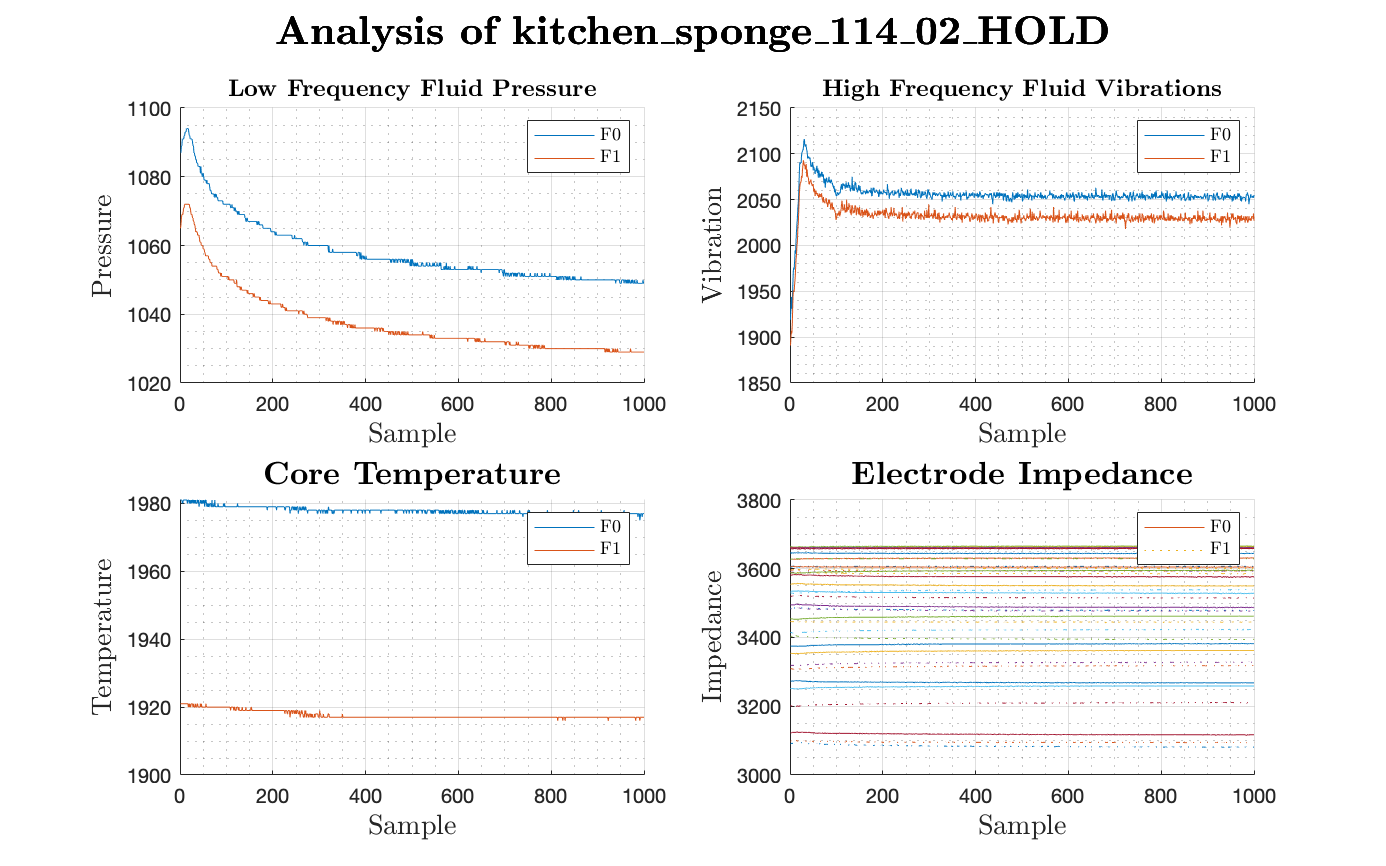

clc, clear, close all

% load data
fileName = 'kitchen_sponge_114_02_HOLD';
load(strcat('PR_CW_DATA_2021','/',fileName,'.mat')) 

% plot pressure
figure(1)
set(gcf,'position',get(0,'ScreenSize'))
subplot(2,2,1)
hold on
plot(F0pdc)
plot(F1pdc)
legend(['F0';'F1'],'Interpreter', 'Latex')
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{Low Frequency Fluid Pressure}','Interpreter', 'Latex', 'Fontsize', 12)

% plot vibration
subplot(2,2,2)
hold on
plot(F0pac(2,:))
plot(F1pac(2,:))
legend(['F0';'F1'],'Interpreter', 'Latex')
grid on
grid minor
xlabel('Sample','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{High Frequency Fluid Vibrations}','Interpreter', 'Latex', 'Fontsize', 12)

% plot temperature 
subplot(2,2,3)
hold on
plot(F0tdc)
plot(F1tdc)
legend(['F0';'F1'],'Interpreter', 'Latex')
grid on
grid minor
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Temperature', 'Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{Core Temperature}','Interpreter', 'Latex', 'Fontsize', 16)

% plot impedance 
subplot(2,2,4)
hold on
for row=[1:19]
    h1 = plot(F0Electrodes(row,:), 'LineStyle','-');
    h2 = plot(F1Electrodes(row,:), 'LineStyle',':');
end
grid on
grid minor
legend([h1 h2],'F0','F1','Interpreter', 'Latex')
xlabel('Sample', 'Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Impedance', 'Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{Electrode Impedance}','Interpreter', 'Latex', 'Fontsize', 16)


fileName = strrep(fileName, '_', '\_');
%title(['\textbf{Analysis of ', fileName, '}'], 'Fontsize', 20, 'Interpreter', 'Latex')

hold off;

% saveas(figure(1),[pwd '\figures\Section_A_Part_1.jpg']);

#### Part 2: For one finger (F0 or F1), sample the Pressure, Vibration, Temperature time series data into scaler values measured at the time instance (of your selected time step) for each object / trial. Save the data structures together as a .mat file called F0_PVT.mat or F1_PVT.mat. Repeat for the Electrodes data, saving that as another .mat file. Note that all subsequent actions in this coursework will be on the data sets you just created (and therefore only on one of the robot’s fingers).

dirName = 'PR_CW_DATA_2021';
timestep = 500;                                 % sample to use for comparison
PVT = struct;                                   %  struct for data for all materials at chosen timestep
Electrodes = struct;
myDir = dirName;
myFiles = dir(fullfile(dirName,'*.mat'));       % get all mat files in directory
for k = 1:length(myFiles)
  baseFileName = myFiles(k).name;
  fullFileName = fullfile(myDir, baseFileName);
  load(fullFileName);
  % read data from each file into structs - change 'F0' to 'F1' to get data for different finger
  PVT(k).name = baseFileName;
  PVT(k).pressure = F0pdc(timestep);
  PVT(k).vibration = F0pac(2,timestep);
  PVT(k).temperature = F0tdc(timestep);
  Electrodes(k).name = baseFileName;
  Electrodes(k).impedance = F0Electrodes(:,timestep);
  save('F0_PVT.mat', 'PVT')
  save('F0_Electrodes.mat', 'Electrodes')
end

#### Part 3: Create a 3D scatter plot of the complete contents of the PVT .mat file, with the axis as Pressure, Vibration and Temperature, with different colours used for different objects. Use the same colours for the objects throughout this work.

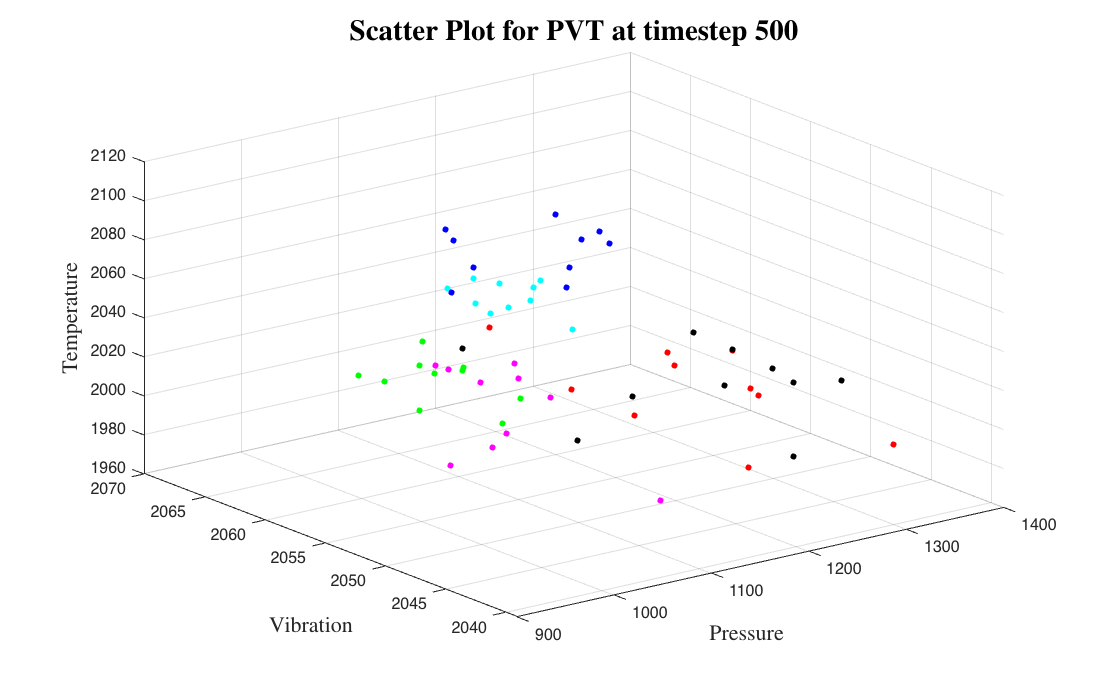


% load data
F0_PVT = load('F0_PVT.mat').PVT;
F0_Electrodes = load('F0_Electrodes.mat').Electrodes;

pressure = zeros(6,10);
vibration = zeros(6,10);
temperature = zeros(6,10);


% get data into individual variables
for object = 1:6
    for sample = 1:10
        i = (object-1)*10 + sample;
        pressure(object,sample) = F0_PVT(i).pressure;
        vibration(object,sample) = F0_PVT(i).vibration;
        temperature(object,sample) = F0_PVT(i).temperature;
    end
end

% scatter plot
figure(2)
scatter3(pressure(1,:),vibration(1,:),temperature(1,:),15,'black','filled')
hold on;
scatter3(pressure(2,:),vibration(2,:),temperature(2,:),15,'blue','filled')
scatter3(pressure(3,:),vibration(3,:),temperature(3,:),15,'cyan','filled')
scatter3(pressure(4,:),vibration(4,:),temperature(4,:),15,'green','filled')
scatter3(pressure(5,:),vibration(5,:),temperature(5,:),15,'magenta','filled')
scatter3(pressure(6,:),vibration(6,:),temperature(6,:),15,'red','filled')

set(gcf,'position',get(0,'ScreenSize'))

xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
title(['\textbf{Scatter Plot for PVT at timestep ', num2str(timestep), '}'],'Interpreter', 'Latex', 'Fontsize', 18)

hold off;

% saveas(figure(2),[pwd '\figures\Section_A_Part_3.jpg']);